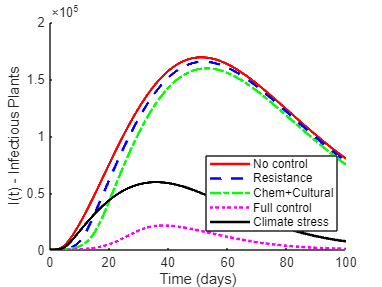


% ==========================================================
% Phomopsis Stem Canker Model
% Climate-Driven Multi-Scenario Simulation
% Revised Chemical and Cultural Interventions
% ==========================================================

clear; clc; close all;

%% Time
tspan = [0 100];

%% Initial conditions
Y0 = [8000 500 300 0 100 200];

%% Climate functions
T = @(t) 25 + 5*sin(2*pi*t/365);
R = @(t) 20 + 10*sin(2*pi*t/365 + 1);
H = @(t) 0.85 + 0.1*sin(2*pi*t/365 + 2);
M = @(t) 0.5 + 0.2*sin(2*pi*t/365 + 1.5);

%% Parameters
Lambda = 40000;
mu = 0.018;

betaP0 = 0.02;
betaC0 = 0.002;

omega0 = 0.04;
sigma = 0.005;
eta = 0.01;

gamma_max = 0.8;
psi = 0.0303;
h = 0.018;
delta = 0.2;

theta = 0.002;
muP = 0.03;
d = 0.1;

%% Scenarios
% Columns: [eps, r, phi, q, er, ec]
%
% eps = resistant cultivar efficacy
% r   = roguing rate
% phi = fungicide efficacy
% q   = cultural clearance rate
% er  = roguing efficacy on residue shedding
% ec  = cultural efficacy on soil transmission
%
% Stronger intervention efficacies are exploratory.

scenarios = {
[0   0   0   0   0   0],      % No control
[0.9 0   0   0   0   0],      % Resistance only
[0   0   0.8 0.4 0   0.8],    % Chem + cultural
[0.4 0.3 0.8 0.4 0.1 0.8],    % Full control
[0.2 0.1 0.1 0.1 0.1 0.05]    % Moderate control
};

names = {'No control','Resistance', ...
         'Chem+Cultural','Full control', ...
         'Climate stress'};

colors = {'r','b','g','m','k'};
styles = {'-','--','-.',':','-'};

results = cell(length(scenarios),1);

%% RUN SIMULATIONS

opts = odeset('RelTol',1e-8,'AbsTol',1e-10);

for i = 1:length(scenarios)

    eps = scenarios{i}(1);
    r   = scenarios{i}(2);
    phi = scenarios{i}(3);
    q   = scenarios{i}(4);
    er  = scenarios{i}(5);
    ec  = scenarios{i}(6);

    odeFun = @(t,Y) model(t,Y,eps,r,phi,q,er,ec,...
        Lambda,mu,betaP0,betaC0,omega0,sigma,eta,...
        gamma_max,psi,h,delta,theta,muP,d,T,R,H,M);

    [t,Y] = ode45(odeFun,tspan,Y0,opts);

    results{i}.t = t;
    results{i}.Y = Y;
end

%% ==========================================================
% PLOT 1: Infectious I(t)
% ==========================================================

figure; hold on;

for i = 1:length(results)

    plot(results{i}.t, results{i}.Y(:,3), ...
        'Color', colors{i}, ...
        'LineStyle', styles{i}, ...
        'LineWidth', 2);
end

legend(names,'Location','best');
xlabel('Time (days)');
ylabel('I(t) - Infectious Plants');

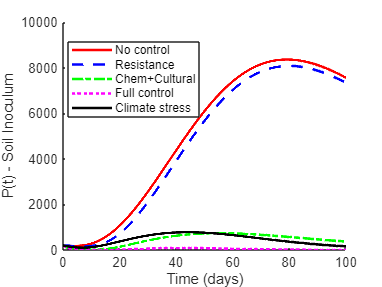


%%grid on;
%%box on;

%% ==========================================================
% PLOT 2: Soil inoculum P(t)
% ==========================================================

figure; hold on;

for i = 1:length(results)

    plot(results{i}.t, results{i}.Y(:,6), ...
        'Color', colors{i}, ...
        'LineStyle', styles{i}, ...
        'LineWidth', 2);
end

legend(names,'Location','best');
xlabel('Time (days)');
ylabel('P(t) - Soil Inoculum');

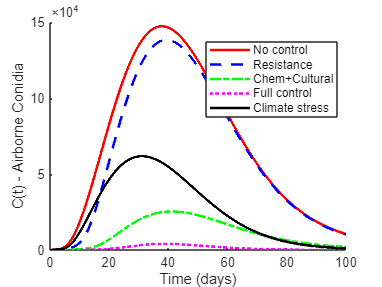


%%grid on;
%%box on;

%% ==========================================================
% PLOT 3: Airborne conidia C(t)
% ==========================================================

figure; hold on;

for i = 1:length(results)

    plot(results{i}.t, results{i}.Y(:,5), ...
        'Color', colors{i}, ...
        'LineStyle', styles{i}, ...
        'LineWidth', 2);
end

legend(names,'Location','best');
xlabel('Time (days)');
ylabel('C(t) - Airborne Conidia');


%%grid on;
%%box on;

%% ==========================================================
% NUMERICAL COMPARISON
% ==========================================================

fprintf('\nCONTROL SCENARIO COMPARISON\n');


CONTROL SCENARIO COMPARISON



I0 = max(results{1}.Y(:,3));
P0 = max(results{1}.Y(:,6));
C0 = max(results{1}.Y(:,5));

for i = 1:length(results)

    Ipeak = max(results{i}.Y(:,3));
    Ppeak = max(results{i}.Y(:,6));
    Cpeak = max(results{i}.Y(:,5));

    redI = 100*(1-Ipeak/I0);
    redP = 100*(1-Ppeak/P0);
    redC = 100*(1-Cpeak/C0);

    fprintf('\n%s\n',names{i});
    fprintf('Peak infectious plants: %.2f\n',Ipeak);
    fprintf('Peak soil inoculum: %.2f\n',Ppeak);
    fprintf('Peak airborne conidia: %.2f\n',Cpeak);
    fprintf('Infectious reduction: %.2f %%\n',redI);
    fprintf('Soil reduction: %.2f %%\n',redP);
    fprintf('Airborne reduction: %.2f %%\n',redC);
end

No control


Peak infectious plants: 169034.99


Peak soil inoculum: 8354.89


Peak airborne conidia: 147198.80


Infectious reduction: 0.00 %


Soil reduction: 0.00 %


Airborne reduction: 0.00 %


Resistance


Peak infectious plants: 165162.04


Peak soil inoculum: 8073.87


Peak airborne conidia: 138216.15


Infectious reduction: 2.29 %


Soil reduction: 3.36 %


Airborne reduction: 6.10 %


Chem+Cultural


Peak infectious plants: 159349.58


Peak soil inoculum: 738.79


Peak airborne conidia: 25345.14


Infectious reduction: 5.73 %


Soil reduction: 91.16 %


Airborne reduction: 82.78 %


Full control


Peak infectious plants: 21491.40


Peak soil inoculum: 200.00


Peak airborne conidia: 4059.01


Infectious reduction: 87.29 %


Soil reduction: 97.61 %


Airborne reduction: 97.24 %


Climate stress


Peak infectious plants: 59511.03


Peak soil inoculum: 780.12


Peak airborne conidia: 61713.29


Infectious reduction: 64.79 %


Soil reduction: 90.66 %


Airborne reduction: 58.07 %



%% ==========================================================
% MODEL FUNCTION
% ==========================================================

function dYdt = model(t,Y,eps,r,phi,q,er,ec,...
    Lambda,mu,betaP0,betaC0,omega0,sigma,eta,...
    gamma_max,psi,h,delta,theta,muP,d,T,R,H,M)

S = Y(1);
E = Y(2);
I = Y(3);
Rr = Y(4);
C = Y(5);
P = Y(6);

%% Climate
Temp = T(t);
Rain = R(t);
Hum = H(t);
Moist = M(t);

%% Response functions
fT = exp(-((Temp-25)^2)/(2*5^2));

fR = (1-exp(-0.3*max(0,Rain))) .* ...
     exp(-((max(0,Rain)-20)^2)/(2*10^2));

fH = 1/(1+exp(-30*(Hum-0.9)));

fM = max(0,Moist)/(max(0,Moist)+0.6);

%% Transmission
betaP = (1-ec)*betaP0*fM;

betaC = (1-eps)*(1-phi)*betaC0*fR*fH;

lambda = betaP*(P/(d+P)) + betaC*C;

%% Progression
omega = omega0*fT*fH*fM;

%% Sporulation
gamma = (1-phi)*gamma_max*fT*fH*fR;

%% Soil-to-air transfer
psi_t = psi*fR;

%% ODE system
dS = Lambda - lambda*S - mu*S;

dE = lambda*S - (omega + mu)*E;

dI = omega*E - (sigma + mu + r + eta)*I;

dRr = (sigma + eta)*I - mu*Rr;

dC = gamma*I + psi_t*(P/(h+P)) - delta*C;

dP = theta*(1-er)*I - (muP + q)*P;

dYdt = [dS; dE; dI; dRr; dC; dP];

end
